# hs1D test file

## Add model to the matlab path

% add hs1D files to the directory
% !!!! Data to fill in to test your own case !!!!
MyDirectory='~/Modeles/hs1D';
addpath(genpath(strcat(MyDirectory,'/hs1D_beta')));

## Topographic analysis

fprintf('------------ Start the Topographic Analysis ------------\n');

------------ Start the Topographic Analysis ------------



% !!!! Data to fill in to test your own case !!!!
DEM_filepath='MNT_PF_5m.tif'; % DEM file path to be analyzed
outlet_coordinates=[364778.7,6834822.7]; % coordinates of the outlet from where the cathcment will be extracted
critical_drainage_area=40000; % minimum area to initiate a stream [in number of pixels] 

% get the watershed object extracted from topographic analysis and the
% equivalent hillslope (1D summary of the catchment with two functions: the
% width and the aquifer depth function). See Troch et al. 2003, Bogaart et al. 2006
[watershed_topo,hillslope_equiv]=watershed.test(DEM_filepath,outlet_coordinates,critical_drainage_area);

## Figures from the topographic analysis

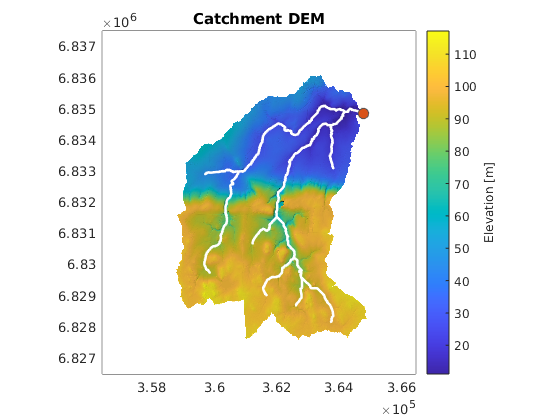

% Catchment map
figure; hold on
imageschs(watershed_topo.DEM);
h = colorbar;
title('Catchment DEM')
ylabel(h,'Elevation [m]');
plot(watershed_topo.S.x,watershed_topo.S.y,'w.')
plot(watershed_topo.Outlet(1),watershed_topo.Outlet(2),'MarkerEdgeColor',[0.33 0.33 0.33],'MarkerFaceColor',[0.8500    0.3250    0.0980],'Marker','o','MarkerSize',8)
box on

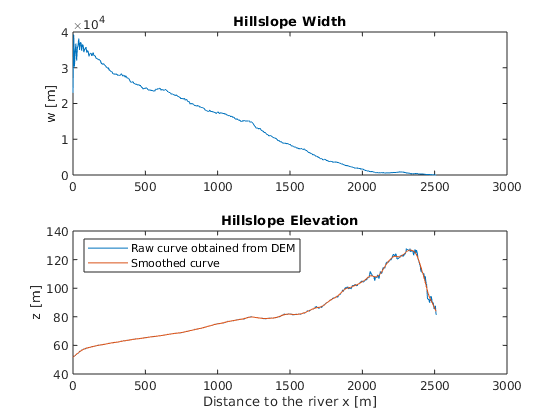


% equivalent hillslope plot
figure; hold on
subplot(2,1,1)
plot(hillslope_equiv.hsB.x,hillslope_equiv.hsB.w) 
title('Hillslope Width')
%xlabel('Distance to the river x [m]')
ylabel('w [m]')
subplot(2,1,2)
hold on
plot(hillslope_equiv.hsB.x,hillslope_equiv.hsB.z)
plot(hillslope_equiv.hsB.x,hillslope_equiv.hsB.z_predicted)
legend('Raw curve obtained from DEM','Smoothed curve','Location','northwest')
box on
title('Hillslope Elevation')
xlabel('Distance to the river x [m]')
ylabel('z [m]')

pause(0.1);
fprintf('Done.\n');

Done.


## Groundwater flow simulation

fprintf('------------ Start the Groundwater Flow Simulation ------------\n');

------------ Start the Groundwater Flow Simulation ------------



% !!!! Data to fill in to test your own case !!!!
Infiltration_filepath='hydrologic_2004_2011_7yrs__semidaily.input';
k=1e-3; % hydraulic conductivity [m/s]
phi_d=0.05;% drainable porosity [-]
river_depth=20; % thickness of the aquifer at the river
aquifer_type='sloped'; % two options: flat aquifer or sloped aquifer
Nx=100; % number of discretized elements

% instantiate hillslope hydraulic parametrizations
hsB_=hillslope_equiv.hsB;
hsB_.f=phi_d;
hsB_.k=k;
if(strcmp(aquifer_type,'flat'))
    hsB_.soil_depth=hsB_.z-hsB_.z(1)+river_depth;
    hsB_.i=zeros(size(hsB_.z));
elseif(strcmp(aquifer_type,'sloped'))
    hsB_.soil_depth=river_depth*ones(size(hsB_.z));
end

% instantiate meteorologic forcing class
source_terms = source.load_source_class_from_txt_file(Infiltration_filepath);
% run transient flow simulation for a given set of value starting from a steady state equal to the mean infiltration time series
recharge_averaged = 1e3*24*3600*source_terms.recharge_mean; % recharge averaged in mm/d
state_values_initial = simulation_set.prerun_steady_state(hsB_,recharge_averaged,1,'empty',Nx); % run with a steady time series to achieve steady state 
presteadystate_percentage_loaded = -2; % -2 is the key to start a simulation with a customed initial condition for storage prescribed in Sinitial
t = source_terms.time.get_properties;  dt = diff(t); dt_mean = mean(dt);
odeset_struct=odeset('RelTol',1e-3,'AbsTol',1e-6,'MaxStep',dt_mean);%30*2.5e-14);%,'Refine',-1);%odeset('RelTol',1e-3);%,'AbsTol',1e-7);%
run_obj=runs;
solver_options=run_obj.set_solver_options(odeset_struct);
run_obj=run_obj.run_simulation(hsB_,source_terms,presteadystate_percentage_loaded,solver_options,1,state_values_initial,'empty',Nx);
% DPSA_: direct precipitaions on saturated areas time series RF_: groundwater flow
[DPSA_,RF_]=compute_DPSA_RF(run_obj.simulation_results,run_obj.boussinesq_simulation);

## Figures from the groundwater flow simulation

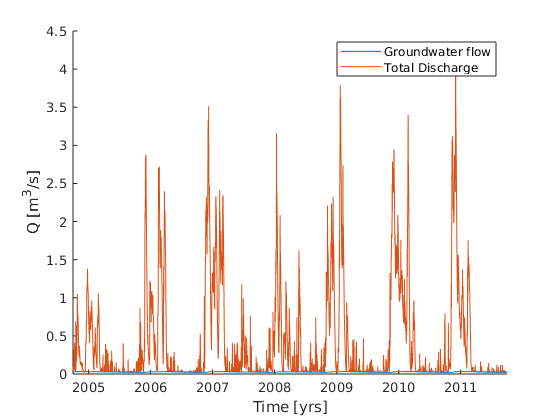

% Discharge vs time 
figure; hold on
t_dt=datetime(datestr(datenum(t/(24*3600)))); % time array in datetime format
plot(t_dt,RF_)
plot(t_dt,RF_+DPSA_)
legend('Groundwater flow','Total Discharge')
xlabel('Time [yrs]')
ylabel('Q [m^3/s]')

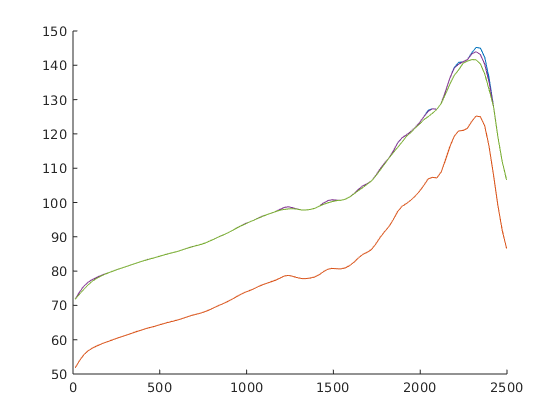

% Hillslope saturation
h=bsxfun(@rdivide,run_obj.simulation_results.S,run_obj.hs1D.f.*run_obj.hs1D.w);
figure; hold on
z_t=run_obj.hs1D.z;
z_b=run_obj.hs1D.z-run_obj.hs1D.soil_depth;
h_init=h(:,1);
S_tot=trapz(run_obj.simulation_results.x_S,run_obj.simulation_results.S);
[~,Ind_max]=max(S_tot);
[~,Ind_min]=min(S_tot);
h_max=h(:,Ind_max(1));
h_min=h(:,Ind_min(1));
plot(run_obj.hs1D.x,z_t)
plot(run_obj.hs1D.x,z_b)
plot(run_obj.hs1D.x,z_b+h_init)
plot(run_obj.hs1D.x,z_b+h_max)
plot(run_obj.hs1D.x,z_b+h_min)

fprintf('Done.\n');

Done.


## Groundwater transport simulation

% fprintf('------------ Start the Groundwater Transport Simulation ------------\n');
% 
% % !!!! Data to fill in to test your own case !!!!
% phi_tot=0.2; % total porosity
% % run transient transport simulation
% [transp,~,t_out,transit_times,travel_distances,weights_,t_inj,~,DPSA_part,GW_part]=transport_2D_par_temp.transport_main(run_obj,phi_tot);
% t_min=0.1; % in yrs
% t_max=12; % in yrs
% time_support=[0,logspace(log10(t_min/10),log10(t_max*10),1000)]*24*365*3600;%
% ttds_=ttds.retrieve_ttds(t_out,transit_times,weights_,travel_distances,x_fin,time_support);
% 
% % Some figures
% fprintf('Done.\n');